# Frequency responses to temperature

clearvars -except hkg hkg2 xxkg xxkg2 
ReFs = 20;

## Constant temp

SINGLE FISH

hkg(63)

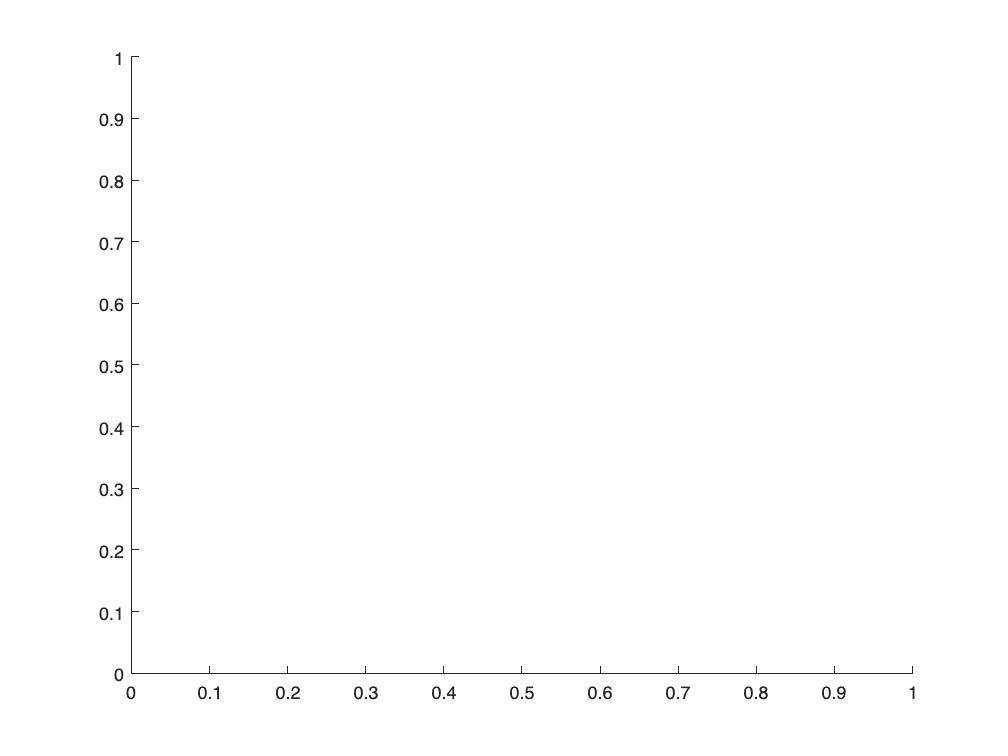

k = 63;
%regularize data
[~, singleconstfreq, singleconstanttemp, ~] = k_dataprepper(hkg(k), 1, ReFs);

% Estimate transfer function from data
[singleconstanttxy, singleconstantf] = tfestimate(singleconstanttemp, singleconstfreq, 1024, 1000, [], ReFs);

MULTI FISH

hkg2(33)

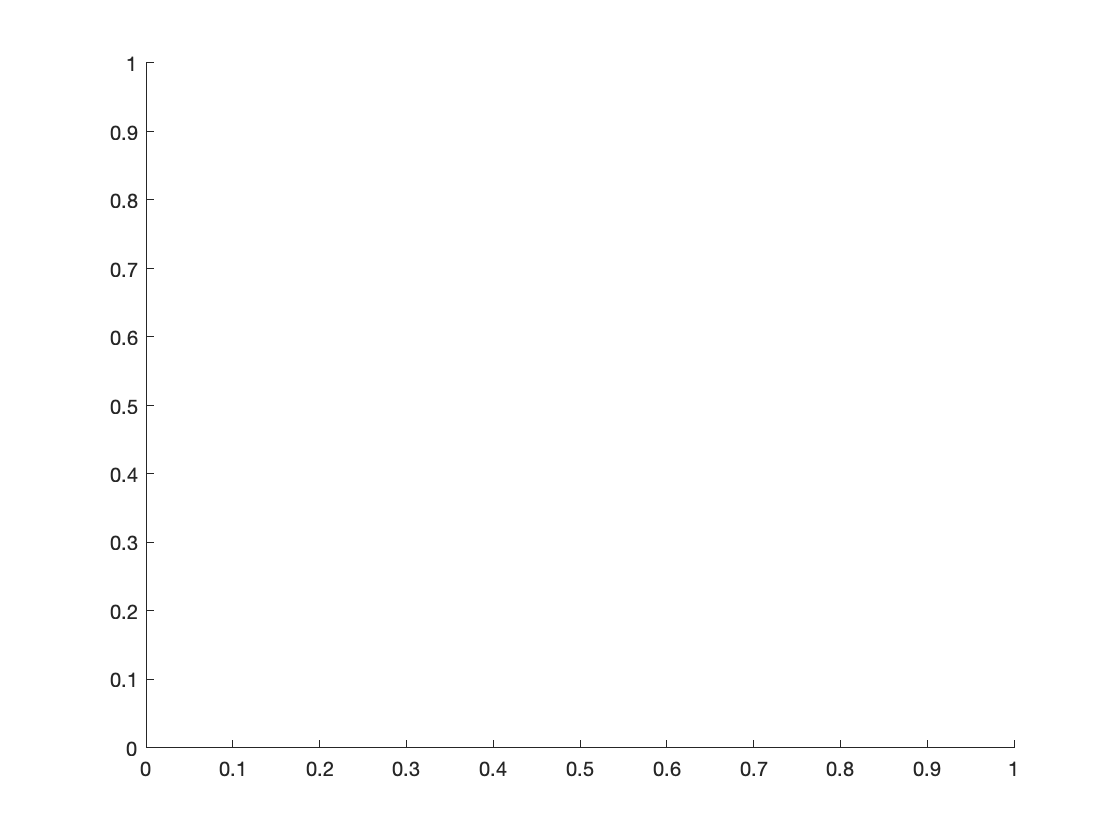

k = 33;
[~, multiconstantfreq, multiconstanttemp, ~] = k_dataprepper(hkg2(k), 3, ReFs);

  [multiconstanttxy, multiconstantf] = tfestimate(multiconstanttemp, multiconstantfreq, 1024, 1000, [], ReFs);

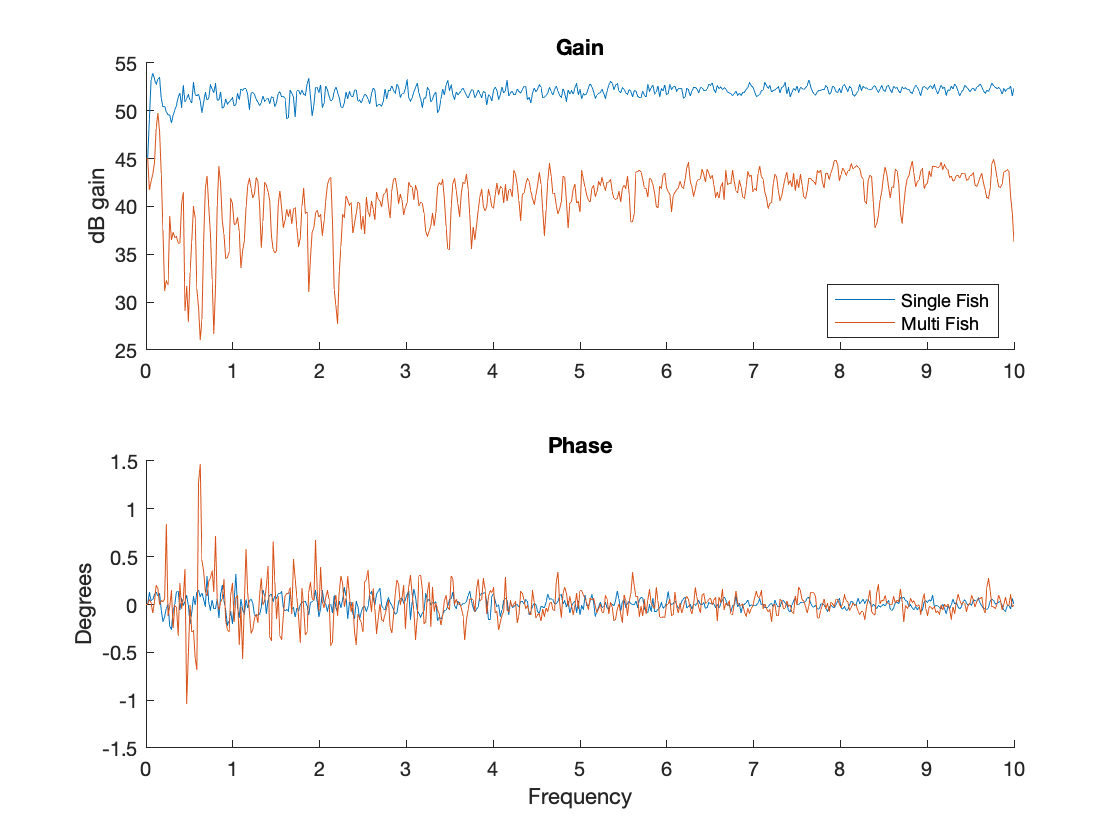

% Plot Bode plot
  figure(111); clf; title('Constant temp');
        ax(1) = subplot(211); hold on;
            loglog(singleconstantf, mag2db(abs(singleconstanttxy)), 'DisplayName', 'Single Fish');
            loglog(multiconstantf, mag2db(abs(multiconstanttxy)), 'DisplayName', 'Multi Fish');
            title('Gain')
            ylabel('dB gain')
            legend('Location','southeast');
        ax(2) = subplot(212); hold on;
            semilogx(singleconstantf, phase(singleconstanttxy));
            semilogx(multiconstantf, phase(multiconstanttxy));
            title('Phase')
            ylabel('Degrees')
            xlabel('Frequency')
            
    linkaxes(ax, 'x');

## Chaning temp

SINGLE FISH

xxkg(14)

k = 14;
[~, singlechangefreq, singlechangetemp, ~] = k_dataprepper(xxkg(k), 1, ReFs);

[singlechangetxy, singlechangef] = tfestimate(singlechangetemp, singlechangefreq, 1024, 1000, [], ReFs);

MULTI FISH

MULTIFISH

hkg2(16)

k = 16;
[~, multichangefreq, multichangetemp, ~] = k_dataprepper(hkg2(k), 3, ReFs);

[multichangetxy, multichangef] = tfestimate(multichangetemp, multichangefreq, 1024, 1000, [], ReFs);

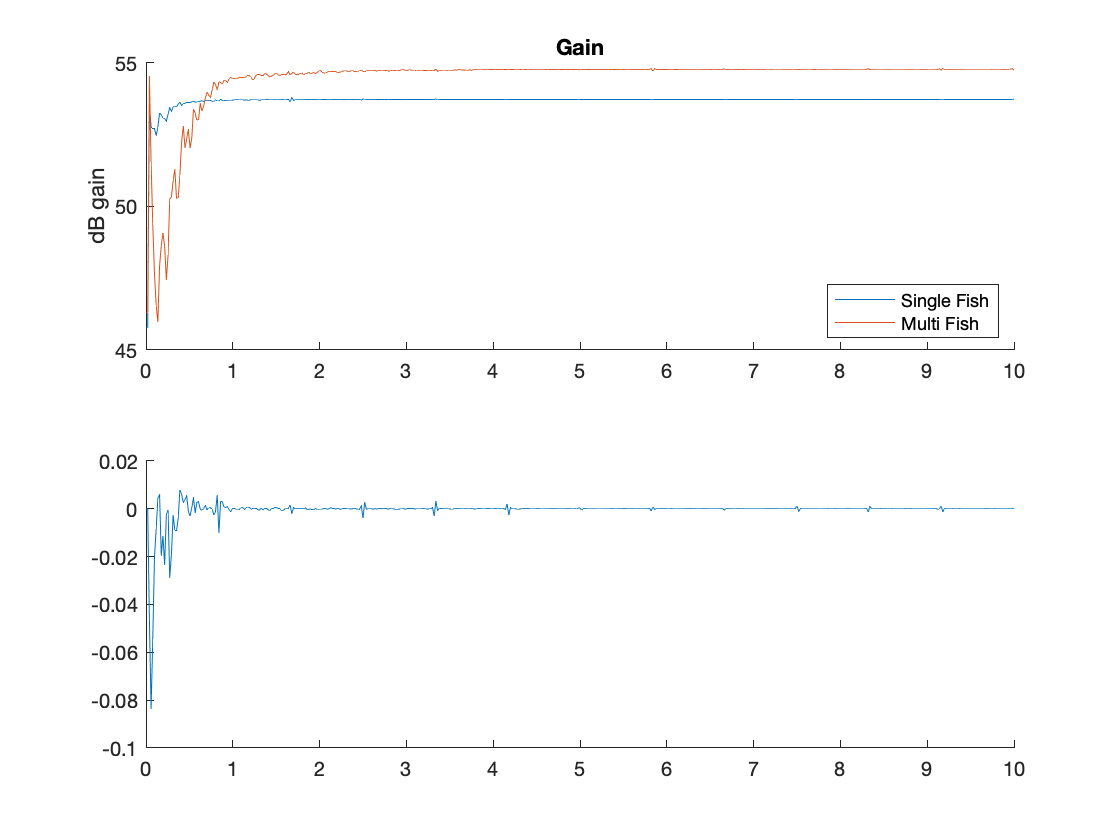

% Plot Bode plot
  figure(112); clf; title('Changed temp');
        ax(1) = subplot(211); hold on;
            loglog(singlechangef, mag2db(abs(singlechangetxy)), 'DisplayName', 'Single Fish');
            loglog(multichangef, mag2db(abs(multichangetxy)), 'DisplayName', 'Multi Fish');
            title('Gain')
            ylabel('dB gain')
            legend('Location','southeast');
        ax(2) = subplot(212); hold on;
            semilogx(singlechangef, phase(singlechangetxy));

            semilogx(multichangef, phase(multichangetxy));

Unrecognized function or variable 'multichangetf'.

            title('Phase')
            ylabel('Degrees')
            xlabel('Frequency')
            